clc
clear
close all

dts_vec = [0.001, 0.002, 0.005, 0.01, 0.02, 0.05, 0.07, 0.09];

out_0_001 = load("./sims/sim_dt_0_001.mat").out;
out_0_002 = load("./sims/sim_dt_0_002.mat").out;
out_0_005 = load("./sims/sim_dt_0_005.mat").out;
out_0_010 = load("./sims/sim_dt_0_010.mat").out;
% out_0_020 = load("./sims/sim_dt_0_020.mat").out;
out_0_025 = load("./sims/sim_dt_0_025.mat").out;
out_0_050 = load("./sims/sim_dt_0_050.mat").out;
out_0_070 = load("./sims/sim_dt_0_070.mat").out;
% out_0_080 = load("./sims/sim_dt_0_080.mat").out;
out_0_090 = load("./sims/sim_dt_0_090.mat").out;

data_struct = {
    out_0_001
    out_0_002
    out_0_005
    out_0_010
    out_0_025
    out_0_050
    out_0_070
    out_0_090
};

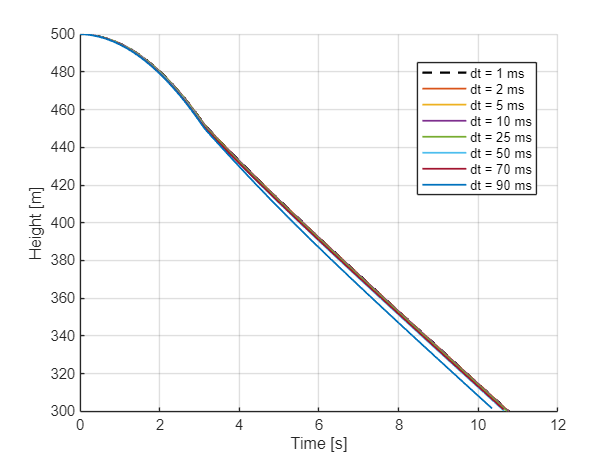

figure(); hold on
plot(out_0_001.main_clock, out_0_001.vehicle_position(:, 3), 'k--', 'LineWidth', 1.5, 'DisplayName', 'dt = 1 ms')
plot(out_0_002.main_clock, out_0_002.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 2 ms')

plot(out_0_005.main_clock, out_0_005.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 5 ms')
plot(out_0_010.main_clock, out_0_010.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 10 ms')
plot(out_0_025.main_clock, out_0_025.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 25 ms')

plot(out_0_050.main_clock, out_0_050.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 50 ms')
plot(out_0_070.main_clock, out_0_070.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 70 ms')
plot(out_0_090.main_clock, out_0_090.vehicle_position(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 90 ms')

legend("Location", "best")
grid on
xlabel("Time [s]")
ylabel("Height [m]")

set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_vehicle_height', '-depsc')  % EPS a cores

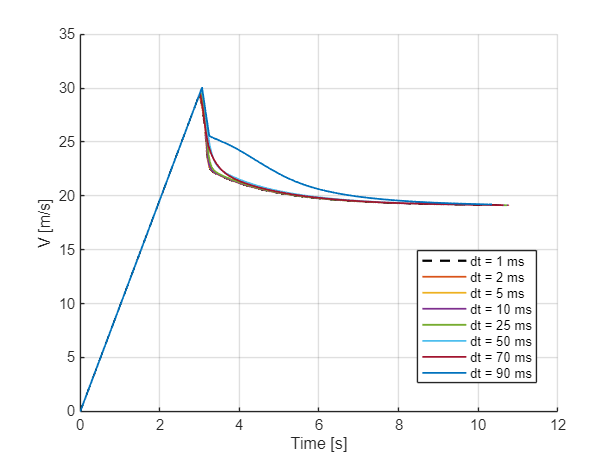


figure(); hold on
plot(out_0_001.main_clock, -out_0_001.vehicle_velocity(:, 3), 'k--', 'LineWidth', 1.5, 'DisplayName', 'dt = 1 ms')
plot(out_0_002.main_clock, -out_0_002.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 2 ms')
plot(out_0_005.main_clock, -out_0_005.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 5 ms')
plot(out_0_010.main_clock, -out_0_010.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 10 ms')
plot(out_0_025.main_clock, -out_0_025.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 25 ms')

plot(out_0_050.main_clock, -out_0_050.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 50 ms')
plot(out_0_070.main_clock, -out_0_070.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 70 ms')
plot(out_0_090.main_clock, -out_0_090.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 90 ms')
legend("Location", "best")
grid on
xlabel("Time [s]")
ylabel("V [m/s]")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_vehicle_velocity', '-depsc')  % EPS a cores

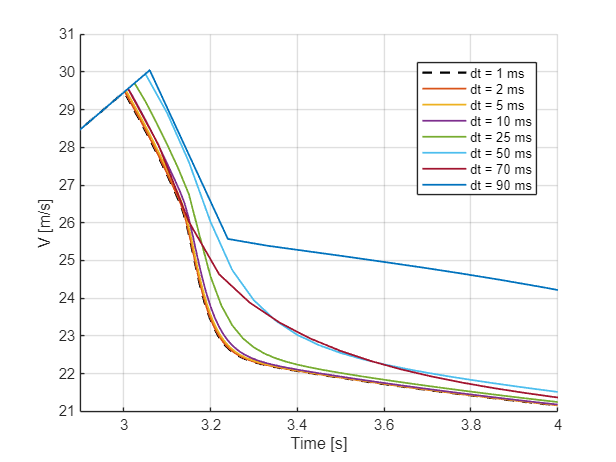



figure(); hold on
plot(out_0_001.main_clock, -out_0_001.vehicle_velocity(:, 3), 'k--', 'LineWidth', 1.5, 'DisplayName', 'dt = 1 ms')
plot(out_0_002.main_clock, -out_0_002.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 2 ms')
plot(out_0_005.main_clock, -out_0_005.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 5 ms')
plot(out_0_010.main_clock, -out_0_010.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 10 ms')
plot(out_0_025.main_clock, -out_0_025.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 25 ms')
plot(out_0_050.main_clock, -out_0_050.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 50 ms')
plot(out_0_070.main_clock, -out_0_070.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 70 ms')
plot(out_0_090.main_clock, -out_0_090.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', 'dt = 90 ms')

legend("Location", "best")
grid on
xlabel("Time [s]")
ylabel("V [m/s]")
xlim([2.9 4])

set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_vehicle_velocity_zoom', '-depsc')  % EPS a cores

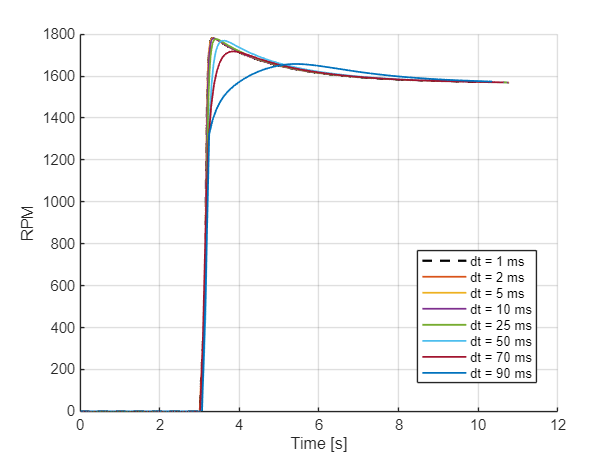

figure(); hold on
plot(out_0_001.main_clock, out_0_001.rotor_rpm, 'k--', 'LineWidth', 1.5, 'DisplayName', 'dt = 1 ms')
plot(out_0_001.main_clock, out_0_001.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 2 ms')
plot(out_0_005.main_clock, out_0_005.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 5 ms')
plot(out_0_010.main_clock, out_0_010.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 10 ms')
plot(out_0_025.main_clock, out_0_025.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 25 ms')
plot(out_0_050.main_clock, out_0_050.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 50 ms')
plot(out_0_070.main_clock, out_0_070.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 70 ms')
plot(out_0_090.main_clock, out_0_090.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 90 ms')
legend("Location", "best")
grid on
xlabel("Time [s]")
ylabel("RPM")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_rotor_velocity', '-depsc')  % EPS a cores

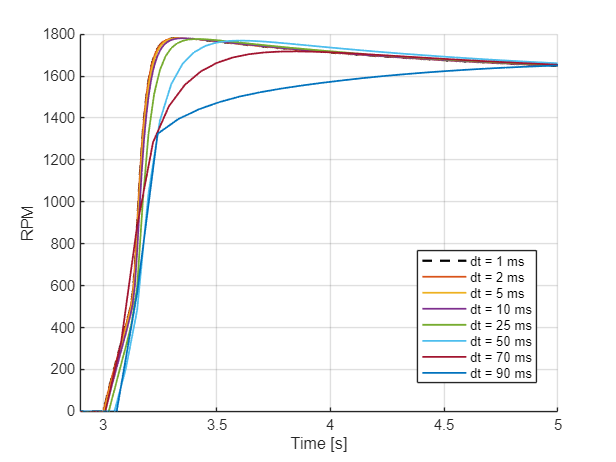


figure(); hold on
plot(out_0_001.main_clock, out_0_001.rotor_rpm, 'k--', 'LineWidth', 1.5, 'DisplayName', 'dt = 1 ms')
plot(out_0_001.main_clock, out_0_001.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 2 ms')
plot(out_0_005.main_clock, out_0_005.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 5 ms')
plot(out_0_010.main_clock, out_0_010.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 10 ms')
plot(out_0_025.main_clock, out_0_025.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 25 ms')
plot(out_0_050.main_clock, out_0_050.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 50 ms')
plot(out_0_070.main_clock, out_0_070.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 70 ms')
plot(out_0_090.main_clock, out_0_090.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', 'dt = 90 ms')
legend("Location", "best")
grid on
xlabel("Time [s]")
ylabel("RPM")
xlim([2.9 5])
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_rotor_velocity_zoom', '-depsc')  % EPS a cores

time_comp = linspace(3.2, 10, 15);

errors_vel = zeros(length(dts_vec)-1, length(time_comp));
errors_rpm = zeros(length(dts_vec)-1, length(time_comp));

for i=2:length(dts_vec)
    for j=1:length(time_comp)   
        [~, index_t_comp] = min(abs(data_struct{1}.main_clock - time_comp(j)));
        [~, index_t] = min(abs(data_struct{i}.main_clock - time_comp(j)));

        vel_comp = data_struct{1}.vehicle_velocity(index_t_comp, 3);
        vel = data_struct{i}.vehicle_velocity(index_t, 3);        
        errors_vel (i, j) = (abs((vel_comp-vel)/(vel_comp))) * 100;

        rpm_comp = data_struct{1}.rotor_velocity(index_t_comp);
        rpm = data_struct{i}.rotor_velocity(index_t);      
        errors_rpm (i, j) = (abs((rpm_comp-rpm)/(rpm_comp))) * 100;
        
    end
end

disp(errors_vel)

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1444    0.0183    0.0090    0.0072    0.0117    0.0090    0.0052    0.0042    0.0032    0.0017    0.0012    0.0019    0.0014    0.0008    0.0006
    0.6122    0.0728    0.0571    0.0484    0.0258    0.0225    0.0175    0.0154    0.0130    0.0099    0.0081    0.0043    0.0036    0.0026    0.0022
    1.5193    0.1067    0.1124    0.0720    0.0755    0.0496    0.0472    0.0324    0.0211    0.0200    0.0128    0.0124    0.0080    0.0074    0.0047
    4.9153    0.5925    0.3766    0.3376    0.2195    0.1961    0.1235    0.1140    0.0998    0.0624    0.0550    0.0341    0.0302    0.0176    0.0158
   11.0922    2.0153    1.6713    1.2060    0.8724    0.6327    0.5486    0.4122    0.2968    0.2551    0.1830    0.1280    0.0903    0.0778    0.0534
    5.1454    1.5564    0.6556    0.4634    0.5849    0.4504    0.3406    0.2684    0.2057    

disp(errors_rpm)

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.4251    0.0157    0.0074    0.0058    0.0096    0.0074    0.0043    0.0034    0.0026    0.0013    0.0010    0.0016    0.0012    0.0006    0.0005
    1.8851    0.0624    0.0476    0.0400    0.0206    0.0181    0.0142    0.0124    0.0105    0.0082    0.0066    0.0036    0.0028    0.0020    0.0018
    4.9044    0.0892    0.0927    0.0581    0.0610    0.0397    0.0386    0.0259    0.0167    0.0167    0.0100    0.0108    0.0063    0.0060    0.0037
   16.0972    0.5076    0.3104    0.2769    0.1746    0.1582    0.0997    0.0911    0.0812    0.0546    0.0438    0.0284    0.0239    0.0135    0.0127
   34.0710    1.2972    1.3967    0.9941    0.7124    0.5101    0.4498    0.3335    0.2375    0.2117    0.1455    0.1025    0.0707    0.0615    0.0421
   18.6558    1.7100    0.2192    0.2978    0.4311    0.3327    0.2542    0.1987    0.1520    

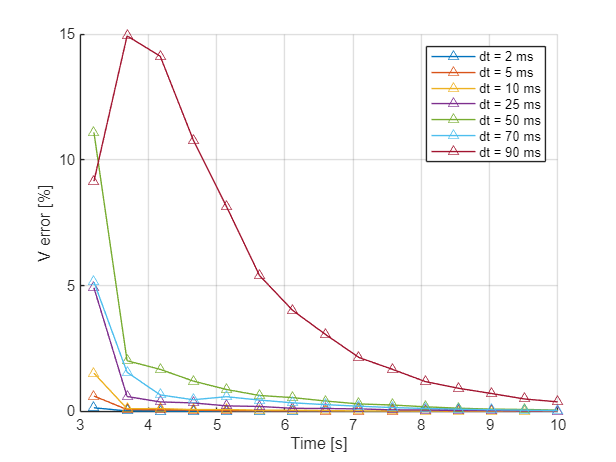

figure()
hold on;
grid on;
for i=2:length(dts_vec)
    plot(time_comp, errors_vel(i, :), "-^")
end
xlabel("Time [s]")
ylabel("V error [%]")
legend('dt = 2 ms', ...
    'dt = 5 ms', ...
    'dt = 10 ms', ...
    'dt = 25 ms', ...
    'dt = 50 ms', ...
    'dt = 70 ms', ...
    'dt = 90 ms')
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_vehicle_velocity_erros', '-depsc')  % EPS a cores

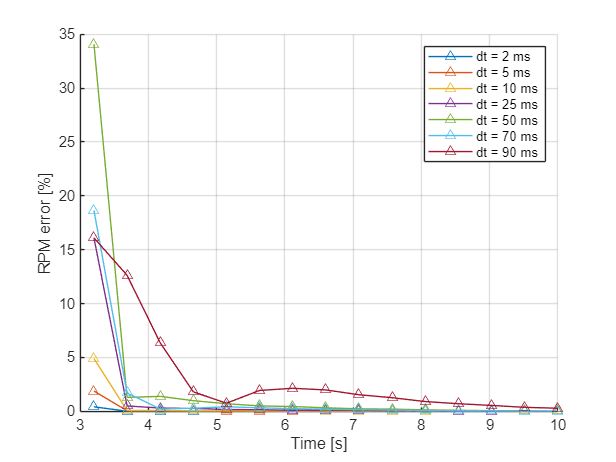



figure()
hold on;
grid on;
for i=2:length(dts_vec)
    plot(time_comp, errors_rpm(i, :), "-^")
end
xlabel("Time [s]")
ylabel("RPM error [%]")
legend('dt = 2 ms', ...
    'dt = 5 ms', ...
    'dt = 10 ms', ...
    'dt = 25 ms', ...
    'dt = 50 ms', ...
    'dt = 70 ms', ...
    'dt = 90 ms')
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'dt_rotor_velocity_erros', '-depsc')  % EPS a cores